% Set up
clc;
close all;
clear;

## load data

## Re-organize data(eeg)

The data is set to m*n matrix

m = number of epochs

n = Frequency of Sampling * epoch length

test = 3

test = 3

EEG1 = []


EEG1 =

     []



EEG2 = []


EEG2 =

     []



STAGE = []


STAGE =

     []



% load test data
edfFilename = sprintf('R%d_edf.mat', test);
xmlFilename = sprintf('R%d_xml.mat', test);
load(edfFilename);
load(xmlFilename);
hdr.label

ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


% We can know from the hdr that the 3rd and the 8th 
% channel of the record is EEG signal
Fs = hdr.samples(3);
% every epoch lasts for epochLength seconds (30 seconds)
numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
% Initialization of eeg1 and eeg2
eeg1 = zeros(numberOfEpochs,Fs*epochLength);
eeg2 = zeros(numberOfEpochs,Fs*epochLength);
epochAmount = 1;    % How much epoches to cut for one row
for i = 1:numberOfEpochs
    epochNumber = i;    % start epoch No.
    epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
    epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
    t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
    eeg1(i,:) = record(8,epochStart:epochEnd);
    eeg2(i,:) = record(3,epochStart:epochEnd);
end
EEG1_test = eeg1;
EEG2_test = eeg2;
% process the stages
stages_epoch = zeros(1,numberOfEpochs);
for i = 1:numberOfEpochs
    stages_epoch(i) = stages(i*30);
end
STAGE_test = stages_epoch;

train = 1:10;
train(train == test) = [];
% load train data
for n = train
    edfFilename = sprintf('R%d_edf.mat', n);
    xmlFilename = sprintf('R%d_xml.mat', n);
    load(edfFilename);
    load(xmlFilename);

    % every epoch lasts for epochLength seconds (30 seconds)
    numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
    % Initialization of eeg1 and eeg2
    eeg1 = zeros(numberOfEpochs,Fs*epochLength);
    eeg2 = zeros(numberOfEpochs,Fs*epochLength);
    epochAmount = 1;    % How much epoches to cut for one row
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
        eeg1(i,:) = record(8,epochStart:epochEnd);
        eeg2(i,:) = record(3,epochStart:epochEnd);
    end
    EEG1 = [EEG1;eeg1];
    EEG2 = [EEG2;eeg2];
    % process the stages
    stages_epoch = zeros(1,numberOfEpochs);
    for i = 1:numberOfEpochs
        stages_epoch(i) = stages(i*30);
    end
    STAGE = [STAGE,stages_epoch];
end

## Plot for check

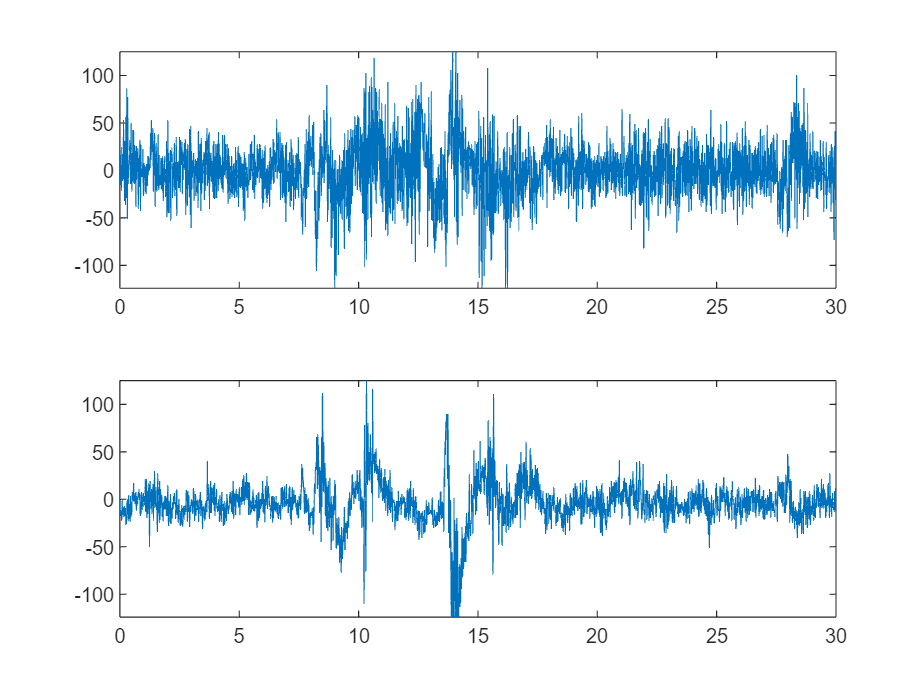

% Plot the first epoch
figure(1)
subplot(2,1,1)
plot(t,EEG1(1,:))
subplot(2,1,2)
plot(t,EEG2(1,:))


% FFT to see frequency domain
% N = 1024;
% EEG1 = abs(fftshift(fft(eeg1(1,:),N)));
% fshift=linspace(-0.5*Fs,0.5*Fs,N);     % fftshift x axis
% figure;
% plot(fshift,EEG1)

## Remove the baseline drift

% It will filter every row
EEG1_filtered = baseline_drift_removal(EEG1,Fs,0.5);
EEG2_filtered = baseline_drift_removal(EEG2,Fs,0.5);

EEG1_test_filtered = baseline_drift_removal(EEG1_test,Fs,0.5);
EEG2_test_filtered = baseline_drift_removal(EEG2_test,Fs,0.5);

## Muscle noise filtering & Power line interference removal

EEG1_filtered = muscle_noise_filtering(EEG1_filtered,Fs,30);
EEG2_filtered = muscle_noise_filtering(EEG2_filtered,Fs,30);

EEG1_test_filtered = muscle_noise_filtering(EEG1_test_filtered,Fs,30);
EEG2_test_filtered = muscle_noise_filtering(EEG2_test_filtered,Fs,30);

## Check changes in frequency domain

% FFT
% N = 1024;
% EEG1_F = abs(fftshift(fft(eeg1_filtered,N)));
% fshift=linspace(-0.5*Fs,0.5*Fs,N);     % fftshift x axis
% figure;
% plot(fshift,EEG1,fshift,EEG1_F)

## Feature Extraction - Time-domain

features_time_eeg1 = extract_time_features(EEG1_filtered);
features_time_eeg2 = extract_time_features(EEG2_filtered);

features_time_eeg1_test = extract_time_features(EEG1_test_filtered);
features_time_eeg2_test = extract_time_features(EEG2_test_filtered);


feature_labels = {'Mean', 'Variance', 'Skewness', 'Kurtosis', ...
                  'Zero-Crossing Rate', 'Hjorth Activity', ...
                  'Hjorth Mobility', 'Hjorth Complexity'};

disp('Characteristics of EEG1 (Time-Domain):');

Characteristics of EEG1 (Time-Domain):


for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg1(i));
end

Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123



disp('Characteristics of EEG2 (Time-Domain):');

Characteristics of EEG2 (Time-Domain):


for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg2(i));
end

Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


## Feature Extraction - Frequency Domain

[features_freq_eeg1, Pxx_eeg1, freqs_eeg1] = extract_freq_features(EEG1_filtered, Fs);
[features_freq_eeg2, Pxx_eeg2, freqs_eeg2] = extract_freq_features(EEG2_filtered, Fs);

[features_freq_eeg1_test, Pxx_eeg1_test, freqs_eeg1_test] = extract_freq_features(EEG1_test_filtered, Fs);
[features_freq_eeg2_test, Pxx_eeg2_test, freqs_eeg2_test] = extract_freq_features(EEG2_test_filtered, Fs);

feature_labels_freq = {'Power Delta', 'Power Theta', 'Power Alpha', 'Power Beta', 'Power Gamma', ...
                      'Spectral Edge Frequency', ...
                      'Relative Delta', 'Relative Theta', 'Relative Alpha', 'Relative Beta', 'Relative Gamma'};

disp('Characteristics of EEG1 (Frequency-Domain):');

Characteristics of EEG1 (Frequency-Domain):


for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg1(i));
end

Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735



disp('Characteristics of EEG2 (Frequency-Domain):');

Characteristics of EEG2 (Frequency-Domain):


for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg2(i));
end

Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


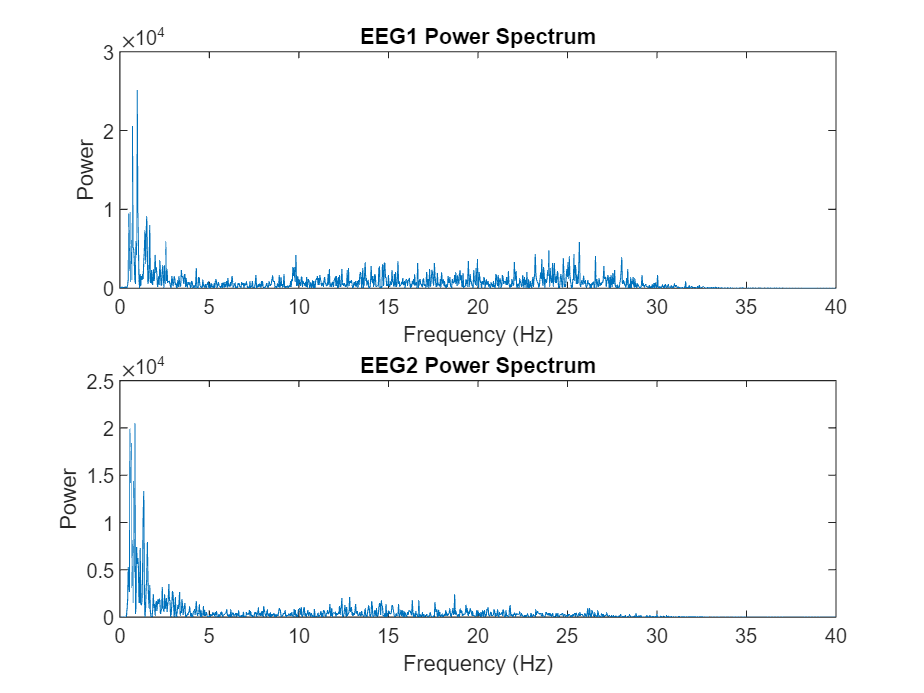


figure;
subplot(2,1,1);
plot(freqs_eeg1, Pxx_eeg1(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG1 Power Spectrum');
xlim([0 40]);

subplot(2,1,2);
plot(freqs_eeg2, Pxx_eeg2(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG2 Power Spectrum');
xlim([0 40]);

## Time Frequency

% Extract time-frequency features
features_timefreq_eeg1 = extract_timefreq_features(EEG1_filtered, Fs);
features_timefreq_eeg2 = extract_timefreq_features(EEG2_filtered, Fs);

features_timefreq_eeg1_test = extract_timefreq_features(EEG1_test_filtered, Fs);
features_timefreq_eeg2_test = extract_timefreq_features(EEG2_test_filtered, Fs);

% Append the new features to the existing feature set
features = [features_time_eeg1, features_freq_eeg1, features_timefreq_eeg1];
features_test = [features_time_eeg1_test, features_freq_eeg1_test, features_timefreq_eeg1_test];

% Display extracted features
disp('Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):');

Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


disp(features_timefreq_eeg1);  

   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.


disp('Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):');

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


disp(features_timefreq_eeg2);  

   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.


disp('Time-Frequency Features for EEG1 (Test Data):');

Time-Frequency Features for EEG1 (Test Data):


disp(features_timefreq_eeg1_test);  

   1.0e+05 *

  Column 1

    0.1154
    0.1885
    0.1769
    0.3640
    0.2606
    0.2059
    0.2212
    0.3865
    1.4254
    0.8788
    0.7361
    0.8859
    1.3040
    0.6158
    0.7597
    0.9449
    1.0728
    1.0639
    0.4323
    0.3994
    1.0649
    2.0857
    2.9858
    2.2114
    2.8378
    1.9265
    0.9956
    1.7689
    2.2907
    0.2249
    1.6158
    1.9842
    0.1330
    0.1408
    1.0674
    1.7848
    1.7544
    1.5005
    2.1988
    1.5057
    2.7905
    0.7160
    0.0749
    0.0667
    0.0730
    0.0901
    0.1100
    0.2337
    0.1506
    0.1718
    0.0927
    0.1273
    0.1160
    0.0881
    0.1266
    0.1133
    0.0959
    0.0826
    0.1410
    0.1245
    0.0813
    0.0866
    0.4410
    0.3738
    0.1134
    0.2255
    0.1266
    0.0646
    0.0895
    0.0845
    0.1455
    0.5799
    0.7312
    1.2601
    0.3978
    0.4657
    0.5654
    0.9895
    1.0683
    0.5010
    0.9287
    0.9542
    2.0653
    1.5503
    2.8128
    2.1327
    2.3549
    1.4822
    1.


disp('Time-Frequency Features for EEG2 (Test Data):');

Time-Frequency Features for EEG2 (Test Data):


disp(features_timefreq_eeg2_test);  

   1.0e+05 *

  Column 1

    0.0568
    0.2098
    0.1984
    0.4619
    0.1475
    0.0620
    0.0587
    1.3653
    0.5739
    1.4291
    0.3259
    0.3682
    1.8423
    0.6699
    0.1225
    0.1042
    0.3334
    0.6487
    0.2483
    0.3220
    0.2894
    0.3362
    0.2594
    0.5100
    0.6444
    0.7806
    1.0259
    0.8458
    0.8137
    0.2194
    1.3044
    0.9753
    0.2866
    0.1352
    0.5517
    0.8609
    1.2695
    1.4756
    1.3227
    0.5281
    1.0709
    0.3345
    0.0906
    0.0676
    0.0787
    0.0849
    0.1050
    0.1103
    0.1059
    0.0814
    0.0801
    0.1112
    0.1003
    0.0998
    0.1143
    0.0824
    0.0857
    0.0645
    0.1071
    0.1202
    0.0725
    0.0623
    0.3525
    0.2800
    0.2875
    0.3632
    0.7848
    0.1118
    0.1304
    0.1654
    0.3058
    0.3294
    0.1877
    0.4234
    0.5558
    0.3025
    0.5519
    0.6049
    0.8206
    0.9036
    0.8244
    0.7004
    1.7432
    1.6035
    2.4246
    1.8134
    2.4223
    1.8527
    1.

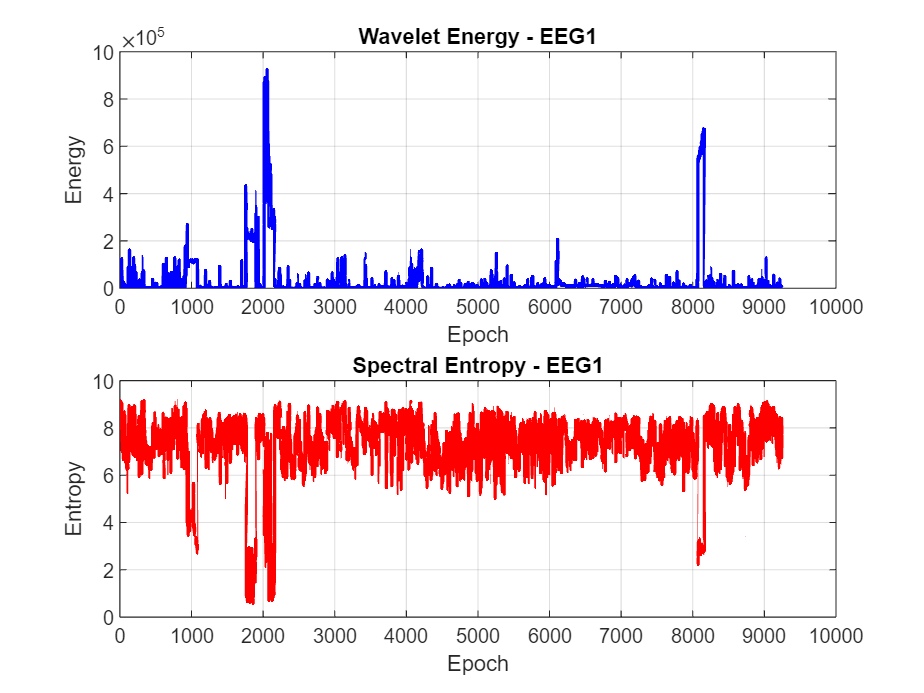


% Plot extracted features for EEG1
figure;

subplot(2,1,1);
plot(features_timefreq_eeg1(:,1), 'b', 'LineWidth', 1.5); 
title('Wavelet Energy - EEG1');
ylabel('Energy');
xlabel('Epoch');
grid on;

subplot(2,1,2);
plot(features_timefreq_eeg1(:,2), 'r', 'LineWidth', 1.5); 
title('Spectral Entropy - EEG1');
ylabel('Entropy');
xlabel('Epoch');
grid on;

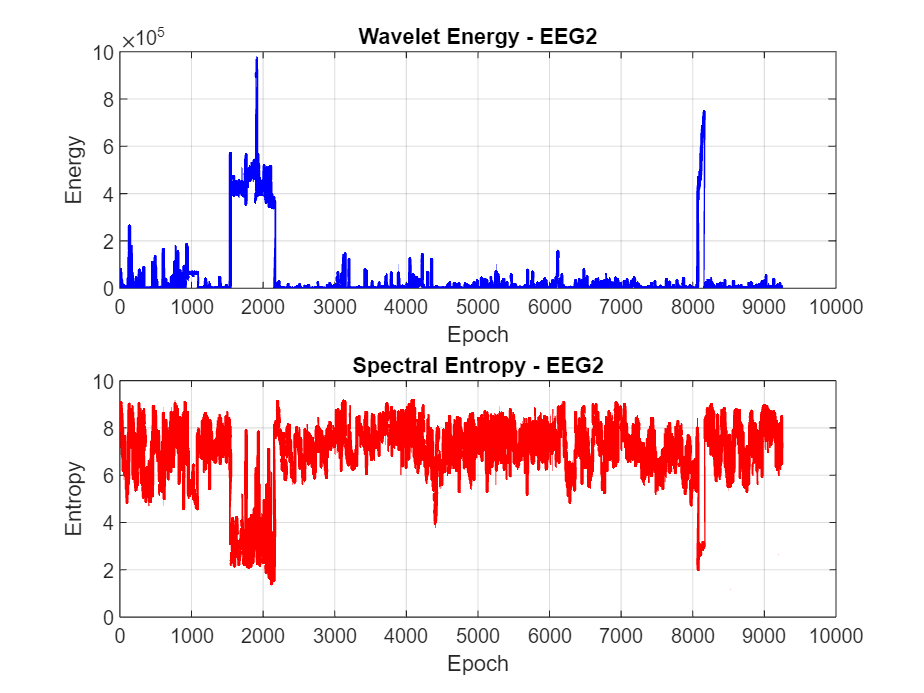


set(gcf, 'color', 'w'); % Set background color to white

% Plot extracted features for EEG2
figure;

subplot(2,1,1);
plot(features_timefreq_eeg2(:,1), 'b', 'LineWidth', 1.5); 
title('Wavelet Energy - EEG2');
ylabel('Energy');
xlabel('Epoch');
grid on;

subplot(2,1,2);
plot(features_timefreq_eeg2(:,2), 'r', 'LineWidth', 1.5); 
title('Spectral Entropy - EEG2');
ylabel('Entropy');
xlabel('Epoch');
grid on;


set(gcf, 'color', 'w'); % Set background color to white



## Classification

features = [features_time_eeg1, features_freq_eeg1];
features = normalize(features);
size(features)

ans =         9245          19


labels = categorical(STAGE, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});
size(labels)

ans =            1        9245


features_test = [features_time_eeg1_test, features_freq_eeg1_test];
features_test = normalize(features_test)

features_test =     1.0469   -0.1940   -0.4944    0.0876    0.9773   -0.1940    0.6953   -0.6408   -0.1932   -0.2197   -0.0561   -0.0797   -0.2494    0.6685   -0.3572   -0.5106    0.1645    0.7301   -0.0546
   -0.2596   -0.0834   -0.0042    2.4007    1.2326   -0.0834    0.7152   -0.5315   -0.0985   -0.2161    0.0100    0.1348   -0.1577    0.7539   -0.0583   -1.0669   -0.1231    0.8001    0.0607
    0.8900   -0.1050   -0.7056    2.1734    1.2548   -0.1050    0.5623   -0.3282   -0.0972   -0.2498   -0.0256   -0.0121   -0.1494    0.5042    0.1179   -1.1443   -0.1024    0.4700    0.1231
   -1.7982    0.2309   -1.8583    1.8157    0.6832    0.2309    0.6494   -0.3926    0.1354    0.1973    0.5684    0.5578    0.3091    0.5567    0.0401   -0.6767   -0.2438    0.5615    0.4833
   -0.2664   -0.1414   -0.9225    0.3549    1.7488   -0.1414    1.5806   -1.1225   -0.2428   -0.1699    0.6769    0.3354   -0.0954    1.5756   -1.3355   -0.5839    0.8029    1.8118    0.3621
    1.2673   -0.1351    0.501

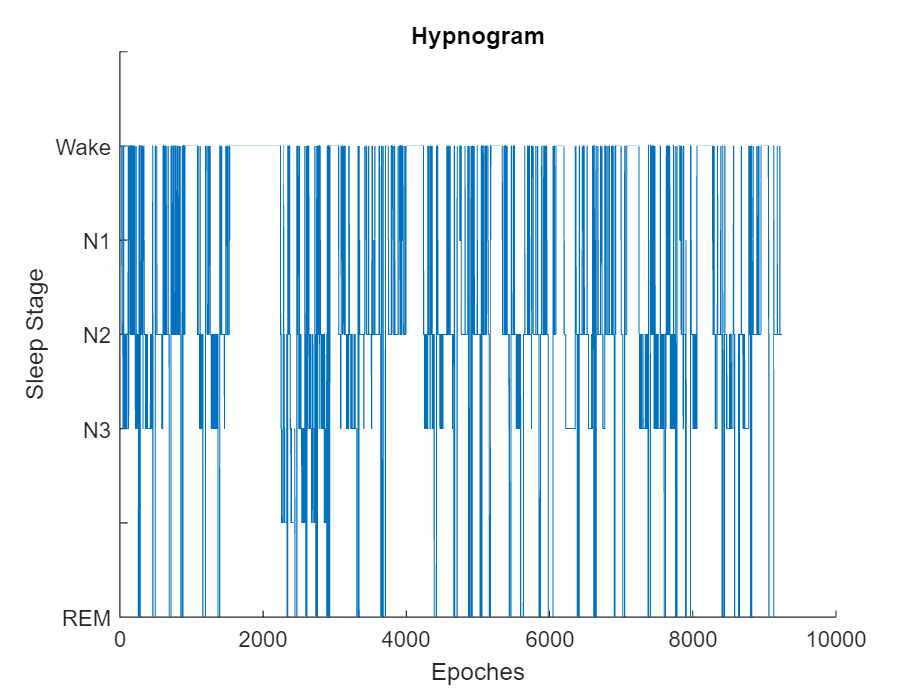

labels_test = categorical(STAGE_test, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});

figure;
plot(STAGE); %sleep stages are for 30 seconds epochs
ylim([0 6]);
set(gca,'ytick',0:6,'yticklabel',{'REM','','N3','N2','N1','Wake',''});
xlabel('Epoches');
ylabel('Sleep Stage');
box off;
title('Hypnogram');

set(gcf,'color','w');

% % Training and test
% [trainedClassifier, validationAccuracy] = trainClassifier(features, labels)
[trainedClassifier, validationAccuracy, f1Score, perStageAccuracy] = trainClassifier3(features, labels)

trainedClassifier = struct with fields:
           predictFcn: @(x)knnPredictFcn(predictorExtractionFcn(x))
    ClassificationKNN: [1×1 ClassificationKNN]
                About: 'This struct is a trained model exported from Classification Learner R2022b.'
         HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 19 columns because this model was trained using 19 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy =     0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.3400    0.0260    0.3806    0.3806    0.3806    0.3400    0.0260    0.3806    0.3806    0.3806    0.3806    0.3806    0.3806    0.3806    0.3806    0.3806    0.1259    0.1259    0.1259    0.1259    0.3806    0.1259    0.1259    0.1259


f1Score = 1

perStageAccuracy =      1
     1
     1
     1
     1
     1


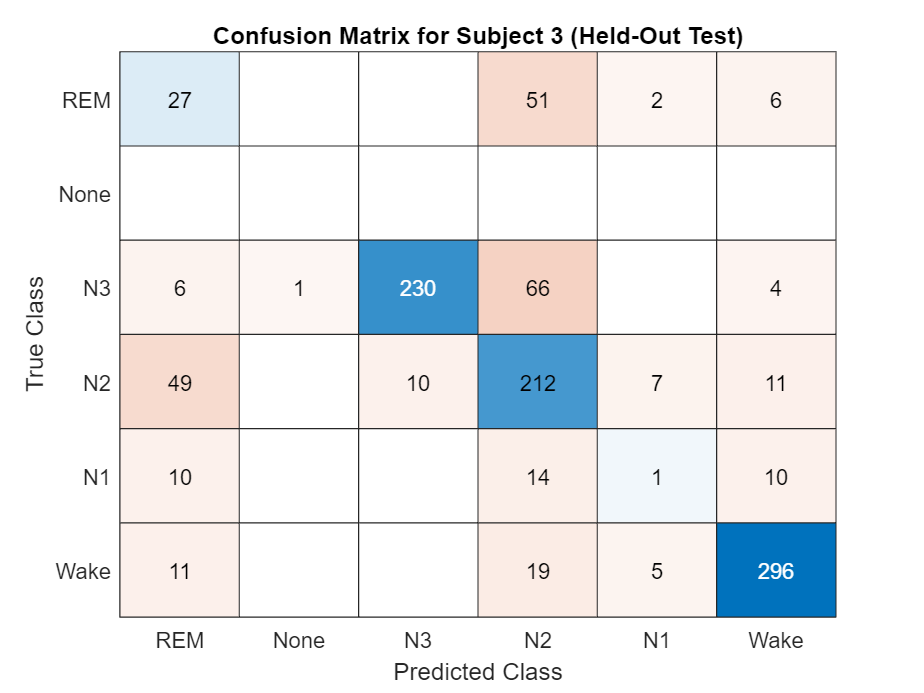

%plot confusion matrix
testPredictions = predict(trainedClassifier.ClassificationKNN, features_test);
confusionchart(labels_test, testPredictions);
title(sprintf('Confusion Matrix for Subject %d (Held-Out Test)', test));